# 第 3 章 数组运算及数组化编程

- MATLAB运算的基本处理单元是**复数阵列型数据**，而不是标量型数据。

- MATLAB为复数阵列型数据设计了两套运算规则：

**                矩阵运算规则和数组运算规则**；

                矩阵、数组及其运算规则是MATLAB计算平台的基础。

- **矩阵与数组的区别**

- 数组中的元素可以是数也可以是字符等，矩阵中的只能是数

- 矩阵是一个数学概念（线性代数里的），数组是个计算机上的概念

- 矩阵和数组的运算规则不同

- 数组可以是一维的（向量）、也可以是二维的或多维的，二维矩阵和二维

- 数组从结构上看没什么区别。MATLAB将服从矩阵运算规则的阵列称为**矩阵**，将服数组运算规则的阵列称为**数组**

# 3.1 数值计算的特点和地位

- **符号计算**：优点是所得结果完全准确; 

                局限性是有很多问题无法解，且求解时间过长

- **数值计算：**适用范围广，能处理各种复杂的函数关系，速度快，容量大。

                数值计算是以有限精度数值为基本操作元素，所以只能用有限长度的数据，

                以有限的精度，表现有限时间和范围内的函数关系。

- 进行数值计算首先要生成由一系列自变量采样点构成的数组，然后计算各采样点的函数值

                数值计算中，无论是自变量还是函数值，都以**离散**形式的**数值数组**表达。

【例3.1-2】已知$f(t)=e^{-\sin (t)}$，求$S(x)=\int_{0}^{4} f(t) d t$。

（1）符号计算解法

syms t x
ft=exp(-sin(t))
sx=int(ft,t,0,4)      %函数不可积返回原积分函数

（2）数值计算解法

dt=0.05;				
t=0:dt:4;			   
Ft=exp(-sin(t));		
Sx=dt*cumtrapz(Ft);	
Sx(end)				%显示数组最后一个元素，即[0,4]区间的定积分值
plot(t,Ft,'*r','MarkerSize',4)
hold on
plot(t,Sx,'.k','MarkerSize',15)
hold off
xlabel('x')
legend('Ft','Sx') 

# 3.2 矩阵、数组及数组化编程

        MATLAB面向数组/矩阵编程和运算：

-  用“**数组或矩阵运算**”模式处理“**借助循环而反复执行的标量运算**”

-  显著提高程序执行速度，书写简洁、便于阅读

**3.2.1 ** **矩阵概念及矩阵运算规则**

**1.**  **矩阵（****Matrix****）概念**

矩阵：按一定次序排列成M行N列的矩形阵列


$$A_{M \times N}=\left[\begin{array}{cccc}{a_{11}} & {a_{12}} & {\cdots} & {a_{1, N}} \\ {a_{21}} & {a_{22}} & {\cdots} & {a_{2 N}} \\ {\vdots} & {\vdots} & {\vdots} & {\vdots} \\ {a_{M 1}} & {a_{A 2}} & {\cdots} & {a_{M N}}\end{array}\right]=\left[a_{i j}\right]_{M \times N}$$


- M=N称为方阵

- AM×1称为列矩阵、列数组或列向量；

- A1×N 称为行矩阵、行数组或行向量；

- A1×1是（1×1）的矩阵，是标量，被认为是只含一个元素的二维数组。

**2.** **矩阵运算规则**

         矩阵加减：                   A+B,  A-B   （相应元素之加减）

        标量与矩阵加减：       b+A,  b-A    （标量与每一个矩阵元素相加减）

        矩阵乘积：                   C=A*B

        标量与矩阵相乘：       b*A             （标量与每一个矩阵元素相乘）

        矩阵除左和右除           X=A\B  (AX=B)  ;    X= A/B   (XA=B)

        矩阵的共轭转置：       B=A'           （转置，共轭）

        方阵的求逆：              若∣A∣≠0，C=inv(A)  或  C=A\eye(N)

        方阵的求幂                   C=A^m；

**3.** **矩阵化****编程**

应该采用矩阵化编程，摆脱传统的“实数标量+循环”的编程思路

【例题】已知矩阵$\mathrm{A}_{2 \times 4}, \quad \mathrm{B}_{4 \times 3}$，，采用两种不同的编程求     

这两个矩阵的乘积$C_{2 \times 3}=A_{2 \times 4} B_{43}$。

（1）以“标量”为基本处理单元的传统编程法


$$c_{i j}=\sum_{k=1}^{l} a_{i k} b_{k j} \quad \forall i=1, \cdots, m ; j=1, \cdots, n |$$


clear							
rng('default')	    % 随机发生器恢复默认设置
A=rand(2,4);			 % rand(m,n)产生均匀分布的m*n随机数组
B=rand(4,3);			 % 
C1=zeros(size(A,1),size(B,2));	%为C预分配内存，加快运算速度
for ii=1:size(A,1)					%<6>
	for jj=1:size(B,2)
		for k=1:size(A,2)
			C1(ii,jj)=C1(ii,jj)+A(ii,k)*B(k,jj);
		end
	end
end										%<12>
C1  

（2）MATLAB求矩阵乘积


C2=A*B									%<13> 

## 3.2.2  数组概念及数组运算规则

**1. 数组感念**

- 数组：标量数据组织成矩形或长方体形的阵列集合；

                        满足数组运算规则的阵列。

- 数组可以是一维数组、二维数组、三维数组及高维数组， 

            其中二维数组是最基础最常用的数组。

            二维数组形式上与矩阵没差别。

- 数组元素的编址（Element Indexing）：6

            全下标编址：用行、列、页序列号 (i，j，k)唯一地标识元素位置

                                    如A(1,1,2) 代表a112；全下标编址最明了直接，最常用。

            单下标编址：用单个序号唯一地确定元素在数组中的位置, 如A(21)

                                    按列从上到下、从左到右依次编号

                                        如对三维数组AMNK，A(M*N+1) 代表 a112

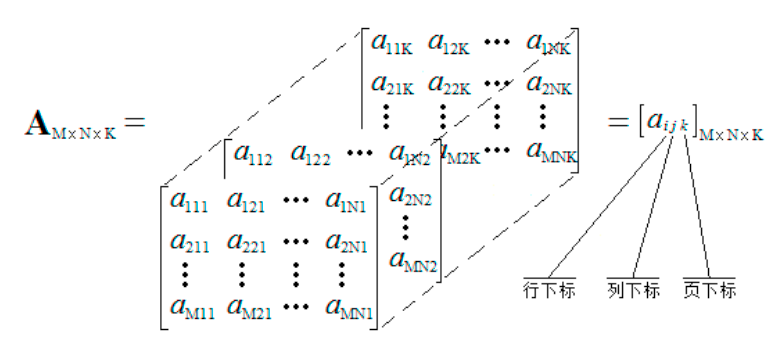

- 行规模为1的数组称为行数组（Row Array）或行向量（Row Vector）

                列规模为1的数组称为列数组(Column Array)或列向量(Column Vector)

                行列规模为1的数组就是标量(scalar)

- 空数组(Empty): 至少有一个维规模为0的数组: $\mathrm{A}_{0 \times \mathrm{N}}, \quad \mathrm{A}_{\mathrm{M} \times 0} \mathrm{A}_{0 \times 0}$

                空数组的最常用M码：[ ]

                MATLAB中，[ ] 可用于缩减数组规模

## 2. 获取数组结构参数的M指令

        N=ndims(A)         维度数目

        S=size(A)             各维度的规模；[r,c]=size(A)； 

        Snd=size(A,nd)    第nd维度上的规模，nd=1(行) ,2(列) ,3(页)

        L=length(A)         数组的长度L（所有维度规模中最大的值）

        Ne=numel(A)       所含元素总数

〖说明〗

- 输入量A可以是数值数组、符号对象数组、字符串数组、胞元数组等

- 在工作空间观察数组结构更方便

【例3.3-1】

A=rand(3,5,2)        % 随机三维数组
N=ndims(A) 
S=size(A)
Snd=size(A,3)
L=length(A)
Ne=numel(A)     % 算符数组运算通则

**3、** **数组运算通则**

下述通则中，算术、关系、逻辑运算符都采用符号“#”表示

- 相同规模的数组运算，体现为“两数组对应元素运算”


$$\mathrm{C}=\mathrm{A}_{\mathrm{M} \times \mathrm{N}} \# \mathrm{B}_{\mathrm{M} \times \mathrm{N}}=\left[\mathrm{a}_{\mathrm{i} j} \# \mathrm{b}_{\mathrm{ij}}\right]_{\mathrm{M} \times \mathrm{N}}=\left[\mathrm{c}_{\mathrm{ij}}\right]_{\mathrm{M} \times \mathrm{N}}$$


- 标量与数组之间的运算，体现为“标量与数组每个元素之间的运算” 


$$\mathrm{C}=\mathrm{a} \# \mathrm{B}_{\mathrm{M} \times \mathrm{N}}=\left[\mathrm{a} \# \mathrm{b}_{\mathrm{ij}}\right] _{\mathrm{M} \times \mathrm{N}}=\left[\mathrm{c}_{\mathrm{ij}}\right]_{\mathrm{M} \times \mathrm{N}}$$


- 初等函数对数组的运算体现为“初等函数对数组中的每个元素的运算”

**4、****算数、关系、逻辑算符**

- 算数运算的参算量可以是双精度类、符号类的任何数，结果是数值

                双精度类型与符号类型数混合运算结果是符号类的数

- 关系运算中的参算量可以是任何数值，结果是1或0的“逻辑类数”

                运算结果中的逻辑1表示“真”，逻辑0表示“假”

- 逻辑运算中的参算量首先被看作是逻辑量，运算结果也是“逻辑类数”

                参量中的逻辑1表示“真”，逻辑0表示“假”

                参算量中的任何非逻辑类的“非精准数0”，都被认作“真”，

                “精准数值0”都被认作“假”。

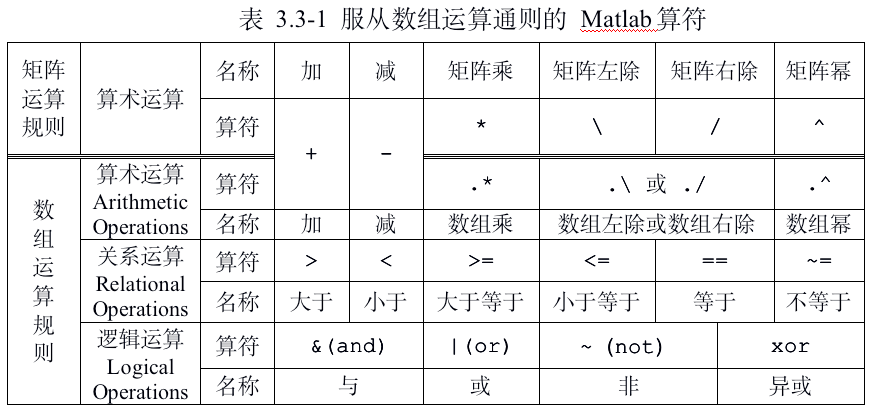

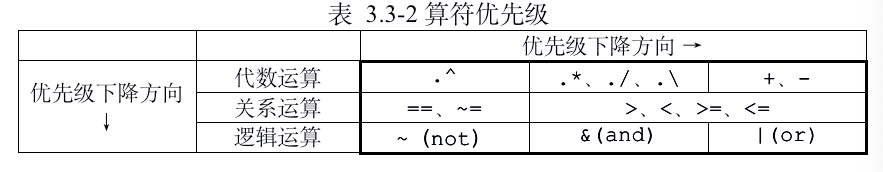

**5****、实施****数组运算的函数**

- 许多针对标量设计的函数都可用于针对数组的运算

- 函数数组运算通则

                初等函数对数组的运算，体现为“初等函数对数组每个元素的运算”


$$Y=f\left(X_{M \times N}\right)=\left[f\left(x_{i j}\right)\right]_{M \times N}=\left[y_{i j}\right]_{M \times N}$$


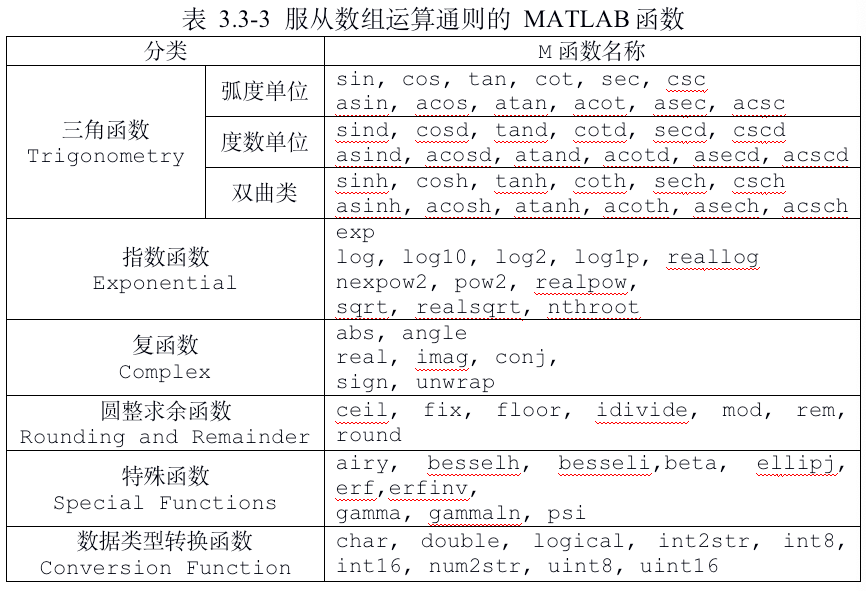

**3.2.3 ****数组和矩阵算术运算规则的功能比较**

理解和掌握矩阵和数组两套运算规则是理解和掌握MATLAB的基础。

矩阵和数组运算规则的异同：

- 相同：加，减；与标量加、减、乘

- 不同：转置，乘，除，求幂

- MATLAB中的数组除与矩阵除有根本区别。

            矩阵有左除\和右除/之分。

            如A是非奇异方阵，左除A\B等价于inv(A)*B，给出恰定方程AX=B的解

            右除B/A等价于B*inv(A)，给出恰定方程XA=B的解

            同规模数组除是相应元素相除

            矩阵除还可应用于满列（或行）秩的非方矩阵。

【例题 】本例演示：矩阵和数组乘法的不同。

（1）创建矩阵和数组

Am=magic(3)			       % 3阶魔方阵
Aa=reshape(1:12,3,4)   % reshape(A,m,n):从矩阵A第一个元素开
B=2*ones(3,4)			      % 始按列每隔m个元素取一个组成n维向量，
                                      %  再从第二个元素开始同样的方法取数组成
                                      %  n维向量，以此类推，组成m×n矩阵

（2）矩阵乘与数组乘不同

Cm1=Am*B				
Ca1=Aa.*B	

（3）矩阵除与数组除不同

Cm2=Am\B
Cm2i=inv(Am)*B
Ca2L=Aa.\B   %数组左除
Ca2R=B./Aa       %右除结果与上相同
Ca2R1=Aa./B      %右除结果不同

**3.2.4 ****数组化编程**

数组化编程的措施：

- 采用“数组运算”模式处理那些借助循环而反复执行的标量运算

- 采用“向量或矩阵运算”模式去执行那些传统上靠多重循环标量运算完成的矩阵计算

- 尽可能用“**数组或矩阵运算**”指令，以提高运算效率 

【例3.2-3】欧姆定律：$r=\frac{u}{i}$，

其中$r,u,i$分别是电阻（欧姆）、电压（伏特）、电流（安培）

验证实验：电阻两端施加电压，测量电阻中流过的电流，然后据测得的

电压、电流计算平均电阻值（测得的电压电流具体数据见下列程序）。

（1）非向量化程序

clear
vr=[0.89,    1.20,    3.09,    4.27,    3.62,    7.71,    8.99,    7.92,    9.70,    10.41];
ir=[0.028,  0.040,  0.100,  0.145,  0.118,  0.258,  0.299,  0.257,  0.308,  0.345];						
% --------------------
L=length(vr);					
for k=1:L
	r(k)=vr(k)/ir(k);		
end	
% ---------------------------
sr=0;            %求电阻值
for k=1:L
	sr=sr+r(k);				
	end
rm=sr/L		    %求均值

（2）向量化程序

clear
vr=[0.89,    1.20,    3.09,    4.27,    3.62,    7.71,    8.99,    7.92,    9.70,    10.41];
ir=[0.028,  0.040,  0.100,  0.145,  0.118,  0.258,  0.299,  0.257,  0.308,  0.345];						
r=vr./ir				% 注意：运算发生在两数组相同位置元素间
rm=mean(r)			% mean(X) : X是向量,求向量个元素的平均值；
% X是矩阵，求矩阵列向量的均值

【例3.2-4】用间距为0.1的水平线和垂直线均匀分割$x \in[-5,5], y \in[-2.5,2.5]$的矩形域，

在所有水平线和垂直线交点上计算函数$z=\sin |x y|$的值，并图示。

（1）非向量化编程

clear
x=-5:0.1:5;    
y=(-2.5:0.1:2.5)';   
N=length(x);  % 101
M=length(y);  % 51
for ii=1:M      % 51行
    for jj=1:N  % 101列
        X0(ii,jj)=x(jj);  %所有格点的x坐标
        Y0(ii,jj)=y(ii);  %所有格点的y坐标
        Z0(ii,jj)=sin(abs(x(jj)*y(ii))); %所有格点的函数值
    end
end  

（2）向量化编程

[X,Y]=meshgrid(x,y);  % 指定矩形域内所有格点的（x,y）坐标
                      % [X,Y] = meshgrid(xgv,ygv) 
% 生成向量xgv,ygv组成的格点坐标值
Z=sin(abs(X.*Y));     % 数组运算计算矩形域所有格点坐标（x,y）对应的函数值
                                                  % 注意：函数f（·）对数组的逐个元素起作用。

（3）比较二维双精度数是否相等

norm(Z-Z0)    %范数接近eps,认为相等。

（4）绘图

surf(X,Y,Z)
xlabel('x')
ylabel('y')
shading interp
view([190,70]) 